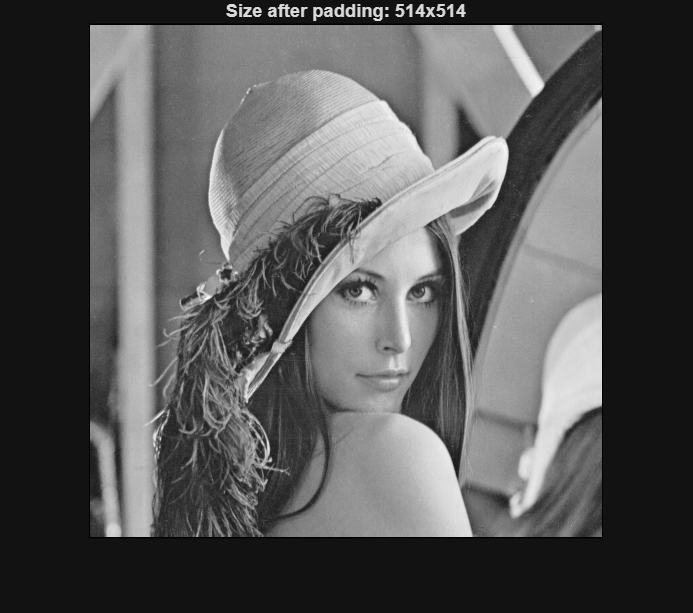

clc;
clear all;
close all;

img = imread('C:\Users\aksha\OneDrive\Desktop\Project\FPGA IO Scripts\lena_greyscale.png');
imshow(img, []);
title(sprintf('Size of input image: %dx%d', size(img,1), size(img,2)));
padded = padarray(img, [1 1], 0, 'both');  % add 1-pixel black border all sides

imshow(padded, []);
title(sprintf('Size after padding: %dx%d', size(padded,1), size(padded,2)));                    % see the numeric matrix

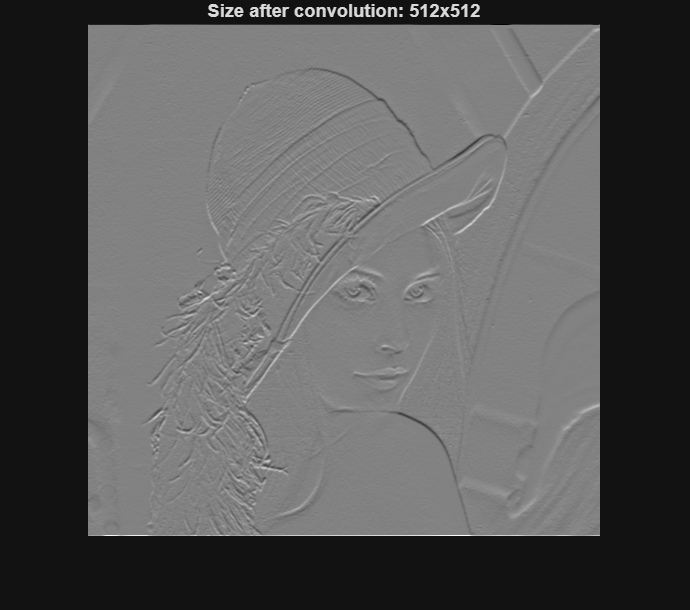

imwrite(padded,'C:\Users\aksha\OneDrive\Desktop\Project\FPGA IO Scripts\padded_image.png');

% ==== Read already padded image ====
B = imread("C:\Users\aksha\OneDrive\Desktop\Project\FPGA IO Scripts\padded_image.png");
if size(B,3) == 3
    B = rgb2gray(B);     % ensure grayscale
end
B = double(B);

% Kernel (Sobel X)
kernel = [1 0 -1;
          2 0 -2;
          1 0 -1];
 
% Dimensions
s = size(B);
k = size(kernel);
rows = s(1) - k(1) + 1;   % valid convolution output rows
cols = s(2) - k(2) + 1;   % valid convolution output cols

% Preallocate new_arr (im2col)
new_arr = zeros(k(1)*k(2), rows*cols);

% Fill new_arr row-major (patches flattened row by row)
count = 1;
for i = 1:rows
    for j = 1:cols
        arr = B(i:i+k(1)-1, j:j+k(2)-1);
        new_arr(:, count) = reshape(arr', [], 1);   % row-major flatten
        count = count + 1;
    end
end

% Flatten kernel & GEMM convolution
new_kernel = kernel(:)';           % 1 x (k1*k2)
conv_out = new_kernel * new_arr;   % (1x9 * 9xN) = 1xN
result = reshape(conv_out, [cols, rows])';

% Display result
figure;
imshow(mat2gray(result));
title(sprintf('Size after convolution: %dx%d', size(result,1), size(result,2)));

imwrite(result, 'C:\Users\aksha\OneDrive\Desktop\Project\FPGA IO Scripts\filtered_image.png');
result;
